# Exercise 2 (Root Locus)

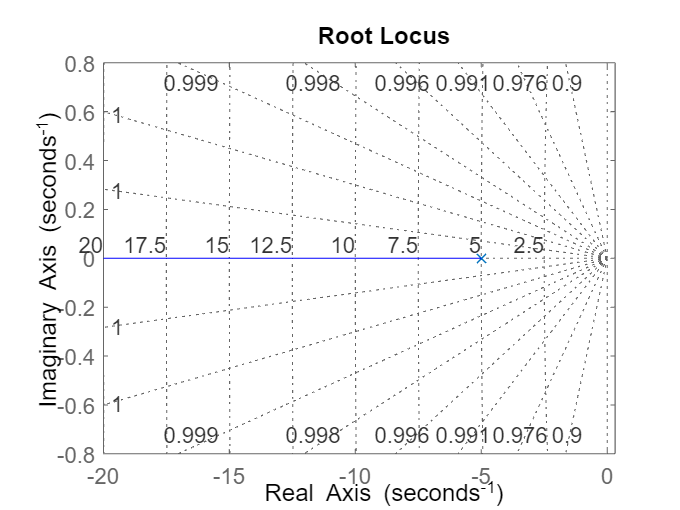

%%a)
sys1 = tf(1,[1 5]);
rlocus(sys1)
grid on

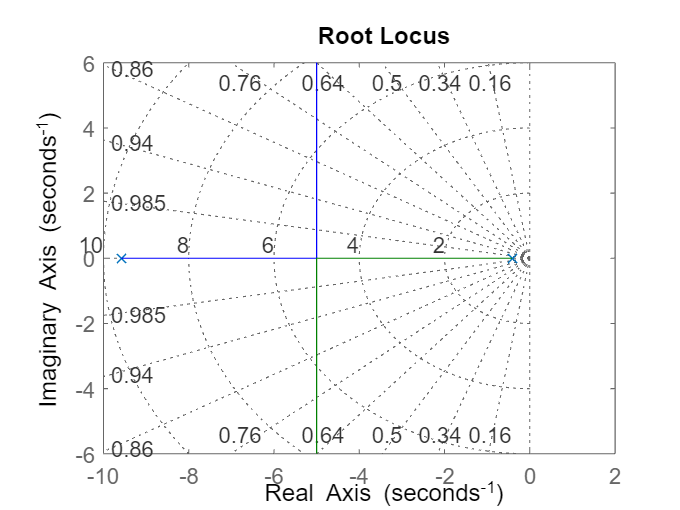

%%b)
sys2 = tf(1,[1 10 4]);
rlocus(sys2)
grid on

%%c)
sys3 = zpk([-3 -4],[-1 -2],1)

sys3 =
 
  (s+3) (s+4)
  -----------
  (s+1) (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


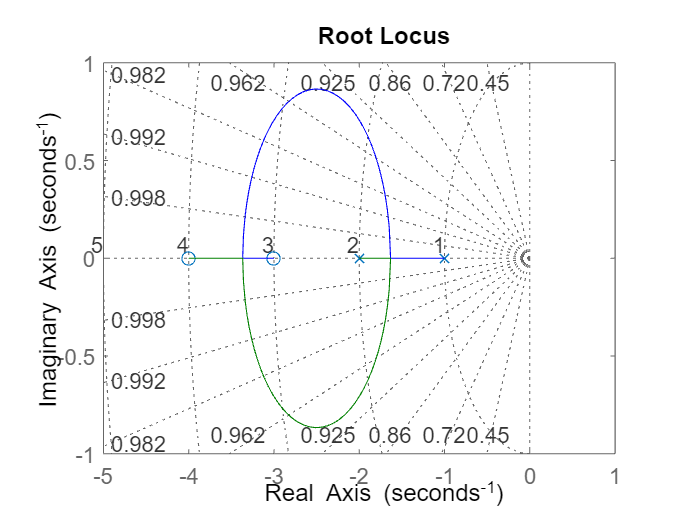

rlocus(sys3)
grid on

%%d)
sys4 = tf([1 4],conv([1 1],[1 10 4])) 

sys4 =
 
           s + 4
  -----------------------
  s^3 + 11 s^2 + 14 s + 4
 
Continuous-time transfer function.
Model Properties


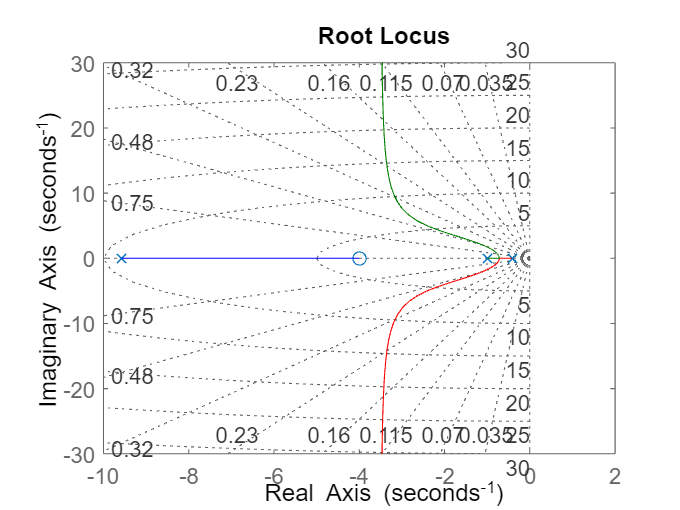

rlocus(sys4)
grid on

%%e)
sys5 = tf([1 -4 20],conv([1 2],[1 4]))

sys5 =
 
  s^2 - 4 s + 20
  --------------
  s^2 + 6 s + 8
 
Continuous-time transfer function.
Model Properties


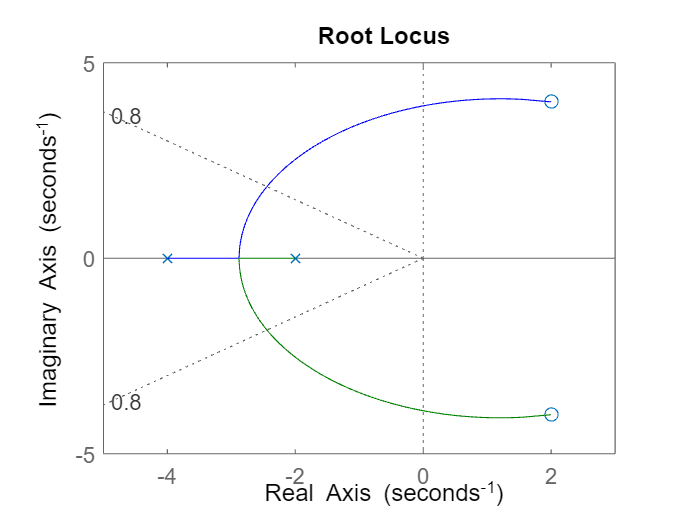

rlocus(sys5)
sgrid(0.8,0)

%%f)
sys6_1 = tf([1 4],[1 2 20])

sys6_1 =
 
      s + 4
  --------------
  s^2 + 2 s + 20
 
Continuous-time transfer function.
Model Properties


sys6_2 = tf(2,[1 7])

sys6_2 =
 
    2
  -----
  s + 7
 
Continuous-time transfer function.
Model Properties


sys6 = sys6_1*sys6_2

sys6 =
 
          2 s + 8
  ------------------------
  s^3 + 9 s^2 + 34 s + 140
 
Continuous-time transfer function.
Model Properties


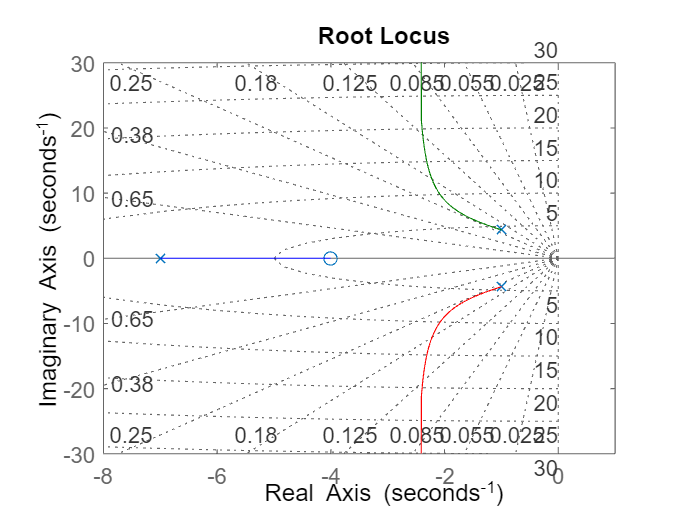

rlocus(sys6)
grid on

%%g)
sys7 = tf(2.3,[0.1 1 0])
rlocus(sys7)
grid on

# SS Error Via Cascade Compensation

## Ideal Integral Compensator

%%Illustration 01
%% Uncompensated
sys_uc = zpk([],[-1 -2 -10],1)

sys_uc =
 
          1
  ------------------
  (s+1) (s+2) (s+10)
 
Continuous-time zero/pole/gain model.
Model Properties


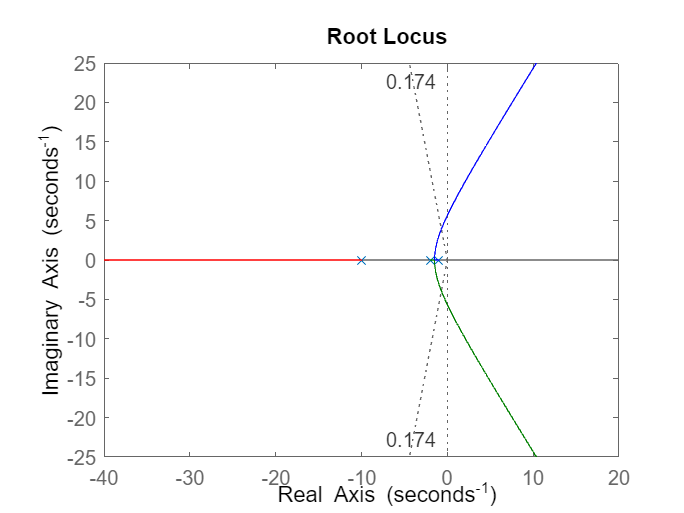

f1 = figure;
rlocus(sys_uc)
sgrid(0.174,0)

%% Compensated
sys_c = zpk(-0.1,[0 -1 -2 -10],1)

sys_c =
 
        (s+0.1)
  --------------------
  s (s+1) (s+2) (s+10)
 
Continuous-time zero/pole/gain model.
Model Properties


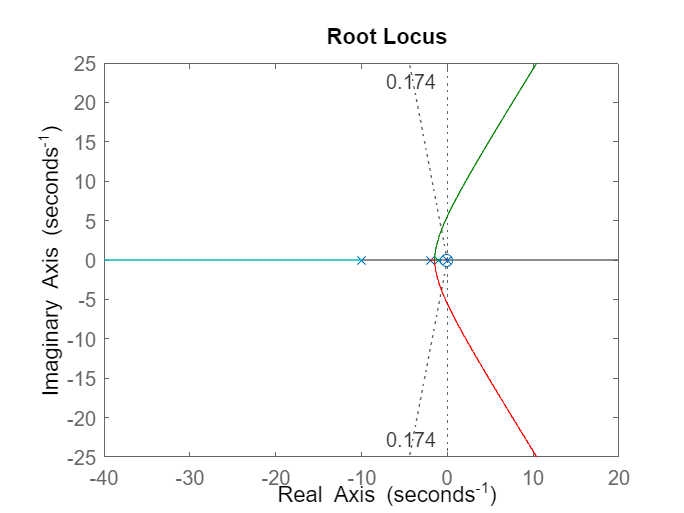

f2 = figure;
rlocus(sys_c)
sgrid(0.174,0)

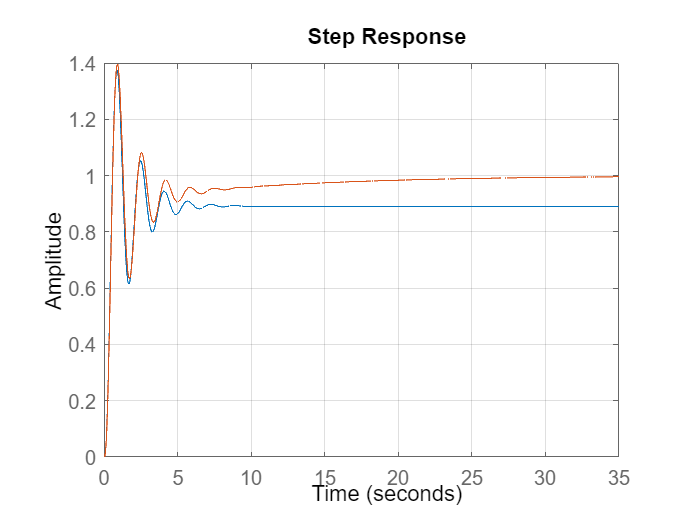

%% Simulation of systems
f3 = figure;
step(feedback(165*sys_uc,1))
hold on
step(feedback(158*sys_c,1))
grid on

%%Example 01
%% Uncompensated
sys_uc2 = zpk([],[-1 -3 -10],1)
f4 = figure;
rlocus(sys_uc2)
sgrid(0.5,0)
%% Compensated
sys_c2 = zpk(-0.2,[0 -1 -3 -10],1)
f5 = figure;
rlocus(sys_c2)
sgrid(0.5,0)
%% Simulation of systems
f6 = figure;
step(feedback(165*sys_uc,1))
hold on
step(feedback(158*sys_c,1))
grid on

## Lag Compensator

%% Uncompensated
sys_uc3 = zpk([],[-1 -2 -10],1)

sys_uc3 =
 
          1
  ------------------
  (s+1) (s+2) (s+10)
 
Continuous-time zero/pole/gain model.
Model Properties


rlocus(sys_uc3)
sgrid(0.174,0)

%% Example 02
sys_uc4 = zpk([],[0 -7],1)

sys_uc4 =
 
     1
  -------
  s (s+7)
 
Continuous-time zero/pole/gain model.
Model Properties


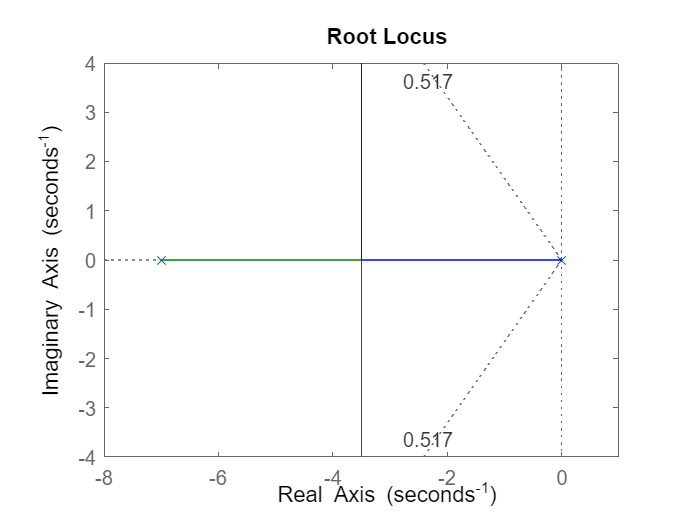

rlocus(sys_uc4)
%%calculate damping ratio with %OS
sgrid(0.517,0)

## Ideal Derivative Compensator

%% Uncompensated
sys_uc4 = zpk([],[-1 -2 -5],1)

sys_uc4 =
 
          1
  -----------------
  (s+1) (s+2) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


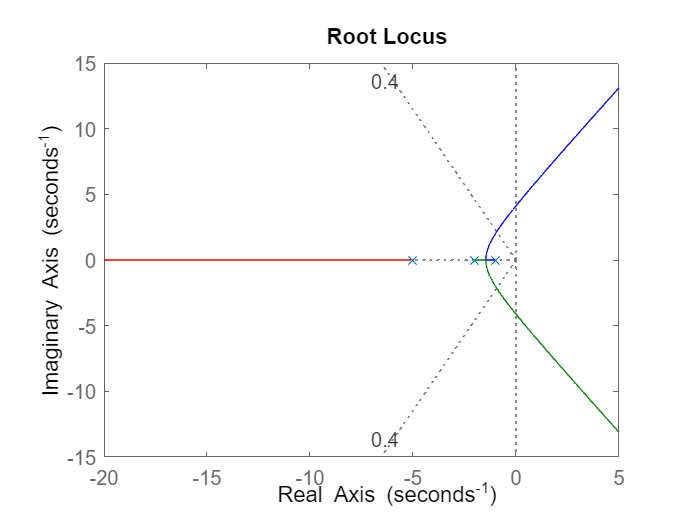

sisotool(sys_uc4)

%% Uncompensated
sys_uc5 = zpk([],[0 -4 -6],1)

sys_uc4 =
 
        1
  -------------
  s (s+4) (s+6)
 
Continuous-time zero/pole/gain model.
Model Properties


sisotool(sys_uc5)

## Lead Compensator

sys_uc6 = zpk([],[0 -4 -6],1)

sys_uc6 =
 
        1
  -------------
  s (s+4) (s+6)
 
Continuous-time zero/pole/gain model.
Model Properties


sisotool(sys_uc6)